##  ECE 537 : Assignment 8

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1.** Load the Exercise 8 data set into matlab. This data comprises a set of 100 time domain data records each comprised of approximately 10,000 samples. This data is noisy, contains measurement discontinuities and spurious data samples. Additionally, each time domain record contains the event denote by the variable event somewhere within each data record.

load('Exercise8_data.mat')

event =     0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000   -0.9877   -0.9511   -0.8910   -0.8090   -0.7071   -0.5878   -0.4540   -0.3090   -0.1564   -0.0000    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000


**Task 2.** Apply statistical goodness-of-fit testing to formally determine whether or not the data can be modeled as having arisen from a stationary and/or ergodic processes across any reasonable time scales.

- check all to see if stationary 

- Amongst stationarity check for ergodicity 

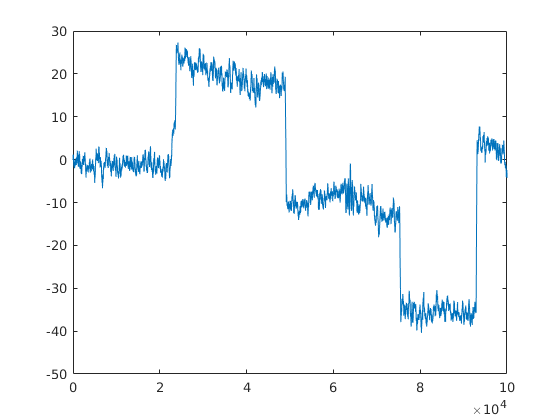

stat_gft = adftest()

% window data 
% take chunk of data and see if
testing imperical dta 


% Vistalization of stationarity of the samples 
plot(data(1).time,movmean(data(1).x,25))

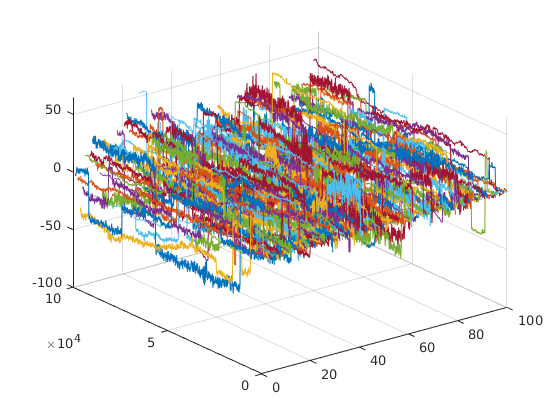

 
% Vistalization of ergodicity of the samples 
for i = 1:100
    plot3((i*ones(size(data(i).x))), data(i).time,movmean(data(i).x,25))
    hold on; 
    grid on; 
end